# **无人机顶层控制算法验证系统设计**

本系统旨在利用MATLAB强大的数值计算与仿真能力，设计并实现一个无人机顶层控制算法的验证系统。该系统包括无人机质点、无人车质点以及环境两大类主要对象，通过定义这些对象的属性、行为及交互函数，模拟无人机与无人车在不同环境条件下的控制效果，从而验证控制算法的可行性和有效性。

系统的优势在于**其重点关注于算法本身，高度抽象化，代码速度基本上只与计算机CPU计算能力、并行计算能力、内存大小及磁盘挂钩，因此其具有良好的迁移性。**

**MATLAB版本的代码可以在任何一台安装了MATLAB2023及以上的电脑上运行**。

接下来我们简要介绍一下环境的组成结构及运行方式，详细的一些运行内容可见**Env_test_files文件夹，该文件夹中含有一些算法的使用示例**：

#### step1：加载环境

run path_add.m

**step2：无人机**

`对于无人机类，其属性有飞行速度`*U*speed`，搜索范围`*U*range`，飞行最大高度`*U*max-altitude`，负载重量`*U*load`，位置`*U*position`，电量`*U*power`，上升消耗系数`*k*up`，平飞消耗系数`*k*around`，下降消耗系数`*k*down`。`

`其中飞行速度决定了无人机类单位时间内能够飞行的路程；搜索范围与任务执行类型相关；飞行最大高度决定了无人机在`XYZ`坐标系中`Z`轴方向的最大位置；负载重量会影响无人机飞行时电量的消耗；位置属性记录了无人机飞行过程中到达过的位置；电量为无人机飞行所需的能量；上升、平飞、下降消耗系数分别反映了无人机上升、平飞以及下降飞行时单位路程消耗的无人机电量。`

max_speed = 10;  % 无人机最大速度
max_range = 60;  % 无人机最大搜索范围
max_altitude = 310;  % 无人机最大飞行海拔
max_power = 2000;  % 无人机最大电量
max_load = 25;  % 无人机最大负载
k_up = 0.05;  % 无人机上升飞行时消耗系数
k_down = 0.01;  % 无人机下降飞行时消耗系数
k_around = 0.03;  % 无人机平飞时消耗系数
dt = 0.1;  % 系统运行时间微元设置
uav_0 = uav(max_speed,max_range,max_altitude,max_power,max_load,k_up,k_down,k_around,dt);  % 初始化无人机
uav_0

uav_0 =   uav - 属性:

       max_speed: 10
       max_range: 60
    max_altitude: 310
       max_power: 2000
        max_load: 25
            k_up: 0.0500
          k_down: 0.0100
        k_around: 0.0300
              dt: 0.1000
           speed: 0
            time: 0
           power: 2000
            load: 12.5000
        position: [0 0 0]


可以看到无人机属性已被初始化，且无人机初始位置位于[0, 0, 0]处，让我们重新初始化一下无人机。

uav_0 = uav_0.current_properties_reset(8/10*max_speed,0,max_power,max_load/2,[-10,-10,1]);  % 重新初始化
uav_0

uav_0 =   uav - 属性:

       max_speed: 10
       max_range: 60
    max_altitude: 310
       max_power: 2000
        max_load: 25
            k_up: 0.0500
          k_down: 0.0100
        k_around: 0.0300
              dt: 0.1000
           speed: 8
            time: 0
           power: 2000
            load: 12.5000
        position: [-10 -10 1]


让我们执行一段简单的无人机飞行任务，接下来我们让无人机从起点出发，飞过下表所列的点：

position_tofly = [0.00	0.00	0.00
500.00	500.00	0.00
219.37	354.68	28.79
190.78	377.34	10.21
382.76	138.01	17.56
397.60	339.85	6.71
93.44	327.55	22.54
244.88	81.31	7.65
222.79	59.50	15.18
323.16	249.18	20.97]; % 待飞行点坐标

for i=1:size(position_tofly, 1)
    uav_0 = uav_0.FlyToNextPoint(position_tofly(i,:), [], [], 1, 1);
end
uav_0

uav_0 =   uav - 属性:

       max_speed: 10
       max_range: 60
    max_altitude: 310
       max_power: 2000
        max_load: 25
            k_up: 0.0500
          k_down: 0.0100
        k_around: 0.0300
              dt: 0.1000
           speed: [3043×1 double]
            time: [3043×1 double]
           power: [3043×1 double]
            load: [3043×1 double]
        position: [3043×3 double]


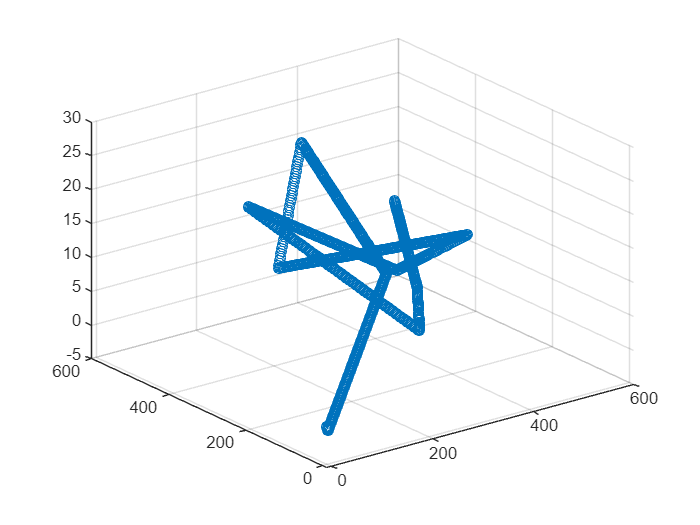

% 将无人机位置绘制出来
figure
scatter3(uav_0.position(:,1),uav_0.position(:,2),uav_0.position(:,3))

此外，无人机类还自带各种灵活的飞行方式。

**step3：无人机与环境交互**

`场地类代表了无人机无人车运行的整体环境，主要为设定的地形特征。以森林环境生成为例`

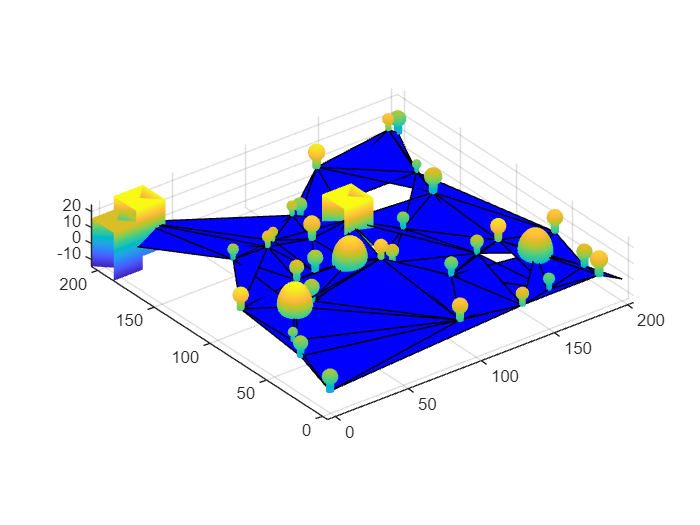

% 场地范围限制
xmin=0;
ymin=0;
xmax=200;
ymax=200;
z_range=10;

% 生成树的信息：x,y,z,体积量(0~1),状态(未燃烧0、燃烧1、燃烧且为着火点2, 长方体3，球体或椭球体4)
n_tree = 30;  % 正常树的数量
n_cuboid = 3;  % 长方体的数量
n_Ellipsoid = 3;  % 椭球体数量
information_tree = [
    xmin,ymin,0,0.9,0;
    xmax,ymax,0,0.9,0;
    ];
n_tree = n_tree - size(information_tree,1);
x_toadd = xmin+(xmax-xmin)*rand(n_tree,1);
y_toadd = ymin+(ymax-ymin)*rand(n_tree,1);
z_toadd = z_range*rand(n_tree,1);
volume_toadd = 0.5+0.5*rand(n_tree,1);
state = zeros(n_tree,1);
information_tree=[information_tree;[x_toadd,y_toadd,z_toadd,volume_toadd,state]];

% 长方体信息
x_cuboid = xmin+(xmax-xmin)*rand(n_cuboid,1);
y_cuboid = ymin+(ymax-ymin)*rand(n_cuboid,1);
z_cuboid = z_range*rand(n_cuboid,1);
volume_cuboid = [20*ones(n_cuboid, 1), 20*ones(n_cuboid, 1), 30*ones(n_cuboid, 1)];
state = 3*ones(n_cuboid, 1);
information_cuboid = [x_cuboid, y_cuboid, z_cuboid, volume_cuboid, state];

% 椭球体信息
x_Ellipsoid = xmin+(xmax-xmin)*rand(n_Ellipsoid,1);
y_Ellipsoid = ymin+(ymax-ymin)*rand(n_Ellipsoid,1);
z_Ellipsoid = z_range*rand(n_Ellipsoid,1);
volume_Ellipsoid = [20*ones(n_Ellipsoid, 1), 20*ones(n_Ellipsoid, 1), 30*ones(n_Ellipsoid, 1)];
state = 4*ones(n_Ellipsoid, 1);
information_Ellipsoid = [x_Ellipsoid, y_Ellipsoid, z_Ellipsoid, volume_Ellipsoid, state];

% 生成树的节点以及场地节点
trees = [];
for i=1:size(information_tree,1)
    temp_tree = tree(information_tree(i,4),information_tree(i,5),information_tree(i,1:3));
    trees=[trees;temp_tree];
end
for i=1:size(information_cuboid,1)
    temp_tree = tree(information_cuboid(i,4:6),information_cuboid(i,7),information_cuboid(i,1:3));
    trees=[trees;temp_tree];
end
for i=1:size(information_Ellipsoid,1)
    temp_tree = tree(information_Ellipsoid(i,4:6),information_Ellipsoid(i,7),information_Ellipsoid(i,1:3));
    trees=[trees;temp_tree];
end
field_tree = field([information_tree(:,1:3);information_cuboid(:,1:3);information_Ellipsoid(:,1:3)]);

% 绘制图像
figure
hold on
draw_trees(trees, field_tree)
hold off

生成好环境以后，比如说我们要执行对该区域的覆盖搜索任务，则有以下流程：

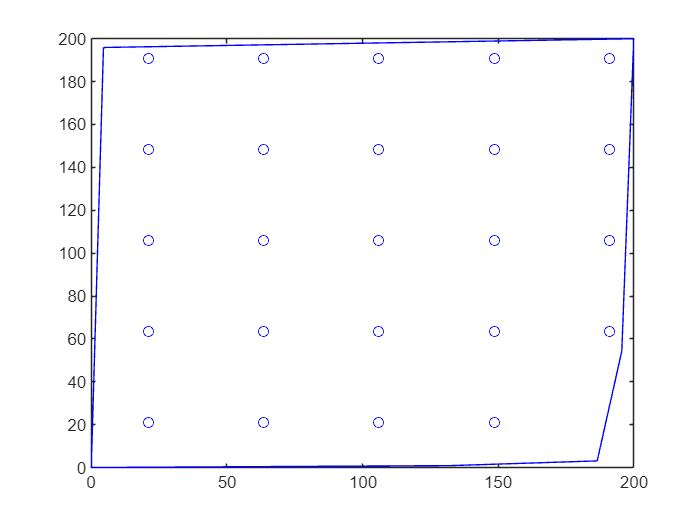

% 找到各个树的2D位置
positions_2D = field_tree.positions(:,1:2);
% 找到树的外接凸多边形坐标
hullpositions_2D = findConvexHull(positions_2D);
r_s = 60; % 无人机搜索半径
task_region = region(hullpositions_2D(1:end-1,:),r_s);
task_region = task_region.region_meshing; % 区域离散化
task_region.region_show;

% 我们利用蛇形搜索算法对区域进行覆盖搜索
% 蛇形搜索算法
snakePath = generateSnakePath(task_region.points_for_drone);  % 利用蛇形搜索算法生成无人机路径

% 初始化一个无人机,并执行飞行过程
altitude_Cruising = field_tree.zmax;  % 巡航海拔高度
uav_1 = uav_0.current_properties_reset(8/10*max_speed,0,max_power,max_load/2,[-10,-10,1]);
for i=1:length(snakePath)
    uav_1 = uav_1.FlyToNextPoint_flexible([snakePath(i,:),altitude_Cruising],[],[],trees,field_tree);
end

% 计算各评价指标，分析算法效果
path1 = uav_1.position(1:5:end,1:2); % 无人机路径
radius = 60; % 无人机搜索半径
polygon = task_region.profile; % 四边形
[coverageRate, ~] = calculateCoverageAndRedundancy(polygon, path1, radius);
pathLength = calculatePathLength(path1);
fprintf('覆盖率: %.2f%%\n', coverageRate * 100);

覆盖率: 100.00%


fprintf('路程长度: %.2f%\n', pathLength);

路程长度: 1027.67

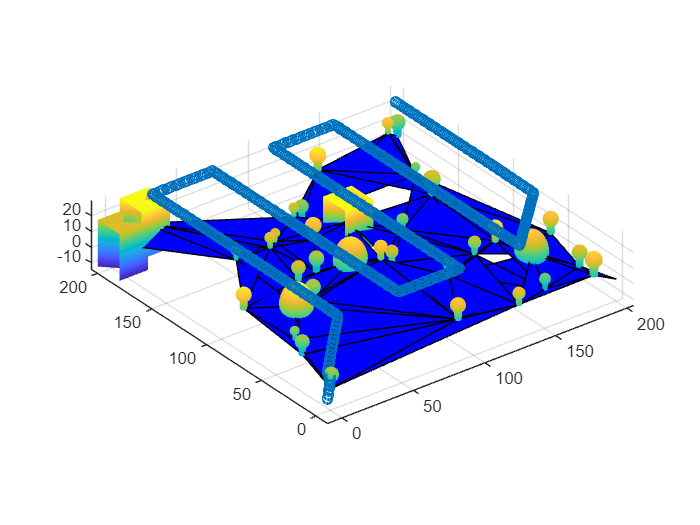

figure
hold on
draw_trees(trees, field_tree)
scatter3(uav_1.position(:,1),uav_1.position(:,2),uav_1.position(:,3))
hold off

读者可自行对系统进行拓展，以执行更加复杂的任务。